clearvars

Lk=1;
n=101;%傅里叶展开次数，奇数次展开
m=81;%迭代式中移相比=m/100，m表示占比的整数值
D=100;%迭代式中占空比=D/100，D表示占空比的整数值
Po=zeros(n);%二维零矩阵
po(:,:,1)=Po;%赋值第一层

for D=1:100
    for beta=1:m
            po(beta,D,1)=-4*(beta/100)^2+4*(D/100)*(beta/100)-2*(D/100)^2+(D/100);
    end
end
[x,y]=meshgrid(0:1:100)

x =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49
     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49
     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49
     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14   

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2
     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3   

z1=po(:,:,1)

z1 =     0.0098    0.0196    0.0290    0.0380    0.0466    0.0548    0.0626    0.0700    0.0770    0.0836    0.0898    0.0956    0.1010    0.1060    0.1106    0.1148    0.1186    0.1220    0.1250    0.1276    0.1298    0.1316    0.1330    0.1340    0.1346    0.1348    0.1346    0.1340    0.1330    0.1316    0.1298    0.1276    0.1250    0.1220    0.1186    0.1148    0.1106    0.1060    0.1010    0.0956    0.0898    0.0836    0.0770    0.0700    0.0626    0.0548    0.0466    0.0380    0.0290    0.0196
    0.0090    0.0192    0.0290    0.0384    0.0474    0.0560    0.0642    0.0720    0.0794    0.0864    0.0930    0.0992    0.1050    0.1104    0.1154    0.1200    0.1242    0.1280    0.1314    0.1344    0.1370    0.1392    0.1410    0.1424    0.1434    0.1440    0.1442    0.1440    0.1434    0.1424    0.1410    0.1392    0.1370    0.1344    0.1314    0.1280    0.1242    0.1200    0.1154    0.1104    0.1050    0.0992    0.0930    0.0864    0.0794    0.0720    0.0642    0.0560    0.0474    

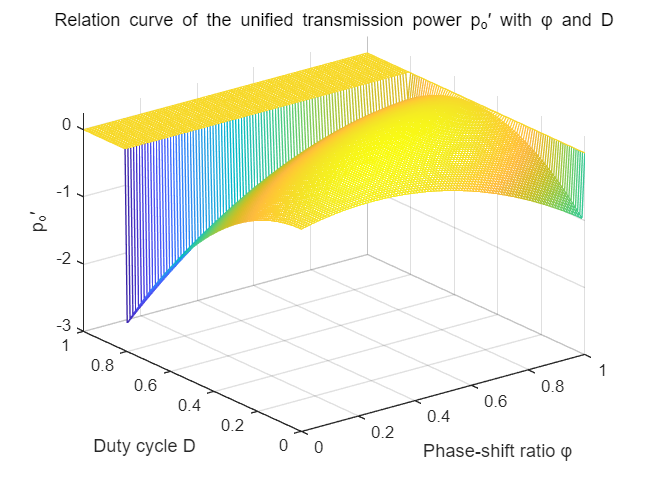

mesh(x,y,z1)
%axis([0,100,0,60,-2,1])
hold on
xlabel('Phase-shift ratio φ') %设置横坐标轴
ylabel('Duty cycle D') %设置纵坐标轴
zlabel('p_o′')
title('Relation curve of the unified transmission power p_o′ with φ and D')
xticks([0 20 40 60 80 100])
xticklabels({0 0.2 0.4 0.6 0.8 1})
yticks([0 20 40 60 80 100])
yticklabels({0 0.2 0.4 0.6 0.8 1})